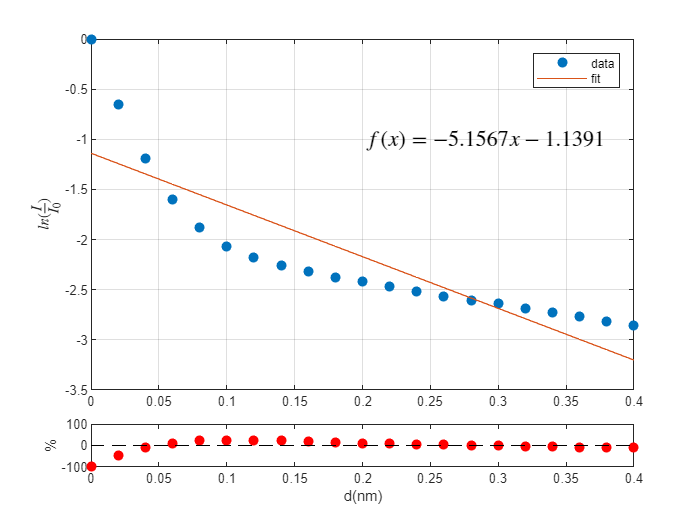

clear
M = {};
cs = ".csv";
for i = 0:20
    re = num2str(i) + cs;
    M = [M readmatrix(re)];
end
M = [M readmatrix("bkg.csv")];
aver = [];
for i = 1:22
    data = cell2mat(M(i));
    [l,~] = size(data);
    timer = 0;
    ave = 0;
    for j = 1:l
        if(data(j,2) == 1)
            ave = ave + data(j,3);
            timer = timer + 1;
        else
            break
        end
    end
    ave = ave/timer;
    aver = [aver ave];
end
aver = aver(1:21) - aver(22);
N = 0:20;
averl = log(aver/aver(1));
N = N*0.02;
f = fit(N',averl','poly1');

tiledlayout('flow','TileSpacing','compact')
g1 = nexttile([5 6]);
hold on
scatter(N,averl,'filled')
plot(N,f(N))
box on
grid on
text(0.2,-1,['$f(x)=' num2str(f.p1) 'x' num2str(f.p2) '$'],'Interpreter','latex','FontSize',13)
legend("data","fit")
ylabel("$ln(\frac{I}{I_0})$","Interpreter","latex")

g2 = nexttile([1 6]);  %散点图
hold on
scatter(N, (averl' - f(N))./f(N)*100,'red','filled')
plot([0 max(N)],[0 0],'k --')
ylabel("%")
xlabel("d(nm)")
ylim([-100 100])
box on